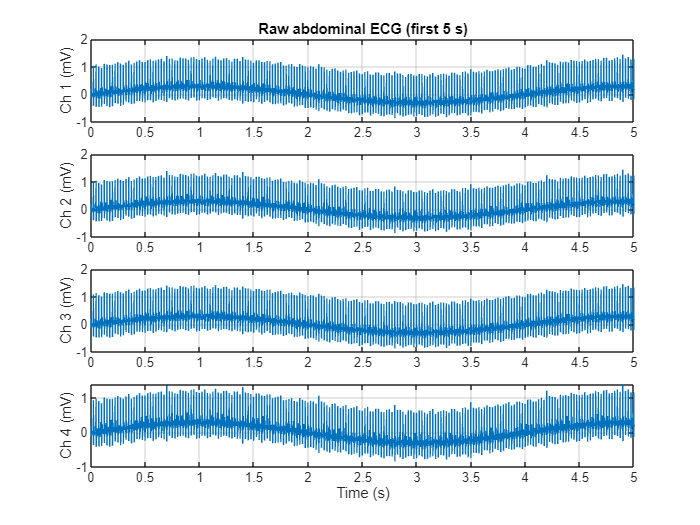

%% EXERCISE 1: Load and inspect ECG data
clear; clc; close all;

% --- Option A: Load real ECG (uncomment if available) ---
% load('FECG_Sample.mat');   % should contain: ecg (channels x samples), Fs
% Fs = 1000;

% --- Option B: Generate synthetic maternal + fetal ECG ---
Fs = 1000;                        % Sampling frequency (Hz)
T  = 20;                          % Duration (s)
t  = 0:1/Fs:T-1/Fs;
N  = length(t);
numCh = 4;

rng(7);                           % Reproducible

% --- Maternal ECG: ~75 bpm (1.25 Hz) ---
mHR  = 75/60;                     % Hz
mQRS = zeros(1,N);
mBeatIdx = round(1:mHR*T:length(t));
for k = mBeatIdx
    if k>0 && k<=N
        mQRS(k) = 1.0;            % sharp QRS spike
    end
end
mKernel = [0 0.15 1.0 -0.3 0 0.05 0 0 0.25 0];
mKernel = mKernel - mean(mKernel);
mECG = conv(mQRS, mKernel, 'same');
mECG = mECG / max(abs(mECG));     % normalise to ~1 mV

% --- Fetal ECG: ~140 bpm (2.33 Hz), much smaller amplitude ---
fHR  = 140/60;                    % Hz
fQRS = zeros(1,N);
fBeatIdx = round(1:fHR*T:length(t));
for k = fBeatIdx
    if k>0 && k<=N
        fQRS(k) = 1.0;
    end
end
fKernel = [0 0.1 1.0 -0.25 0 0.03 0 0 0.15 0];
fKernel = fKernel - mean(fKernel);
fECG = conv(fQRS, fKernel, 'same');
fECG = 0.2 * fECG / max(abs(fECG));   % ~200 µV (realistic FECG range 100-300 µV)

% --- Artifacts and noise ---
drift = 0.3 * sin(2*pi*0.25*t);        % baseline wander
line  = 0.05 * sin(2*pi*50*t);         % power-line interference
emg   = 0.02 * randn(1,N);             % broadband muscle noise

% --- Build multi-channel recording ---
mW = [1.00  0.95  1.05  0.90];
fW = [0.85  1.10  0.70  1.20];
synthetic = zeros(numCh, N);
for ch = 1:numCh
    synthetic(ch,:) = mW(ch)*mECG + fW(ch)*fECG + drift + line + emg;
end
ecg = synthetic;

% Plot raw ECG (all channels, first 5 s)
figure('Name','Raw abdominal ECG','Color','w');
for ch = 1:numCh
    subplot(numCh,1,ch);
    plot(t, ecg(ch,:));
    ylabel(sprintf('Ch %d (mV)', ch));
    grid on; xlim([0 5]);
    if ch == 1, title('Raw abdominal ECG (first 5 s)'); end
    if ch == numCh, xlabel('Time (s)'); end
end

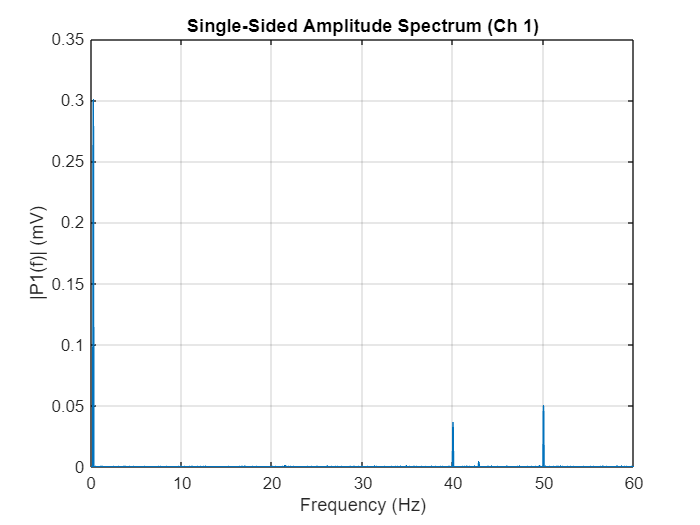

%% EXERCISE 2: PSD via FFT
ch = 1;
x  = ecg(ch,:);
L  = length(x);

Y  = fft(x);
P2 = abs(Y/L);
P1 = P2(1:floor(L/2)+1);
P1(2:end-1) = 2*P1(2:end-1);
f  = Fs*(0:floor(L/2))/L;

figure('Name','FFT Spectrum','Color','w');
plot(f, P1, 'LineWidth', 1.0);
xlabel('Frequency (Hz)'); ylabel('|P1(f)| (mV)');
title('Single-Sided Amplitude Spectrum (Ch 1)');
xlim([0 60]); grid on;

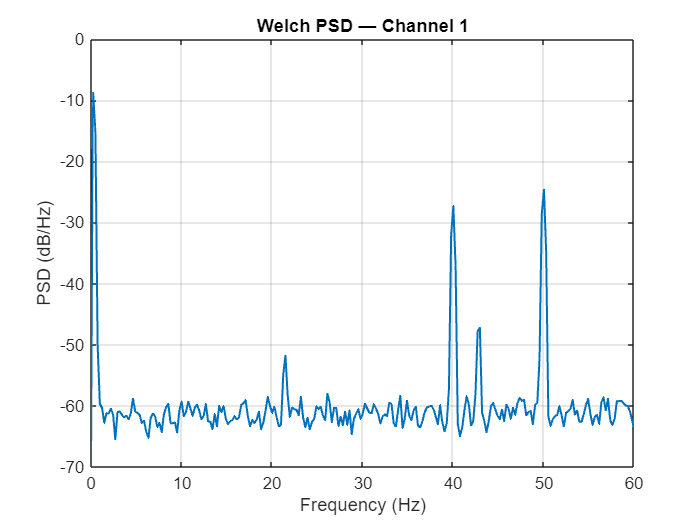

%% EXERCISE 3: Welch PSD
window   = hamming(4*Fs);         % 4 s window
noverlap = round(0.5*length(window));
nfft     = 4096;

[Pxx, fw] = pwelch(x, window, noverlap, nfft, Fs);

figure('Name','Welch PSD','Color','w');
plot(fw, 10*log10(Pxx), 'LineWidth', 1.2);
xlabel('Frequency (Hz)'); ylabel('PSD (dB/Hz)');
title('Welch PSD — Channel 1');
grid on; xlim([0 60]);

%% EXERCISE 4: Band power computation
bands = { 'Baseline',[0.05 0.5]; 'Maternal QRS',[0.5 12];
          'Fetal QRS',[15 40];   'EMG',[40 100] };

fprintf('\nBand power (Ch 1) using Welch PSD:\n');


Band power (Ch 1) using Welch PSD:


fprintf('%-14s %-12s %-12s\n','Band','Range (Hz)','Power (dB)');

Band           Range (Hz)   Power (dB)  


totalPower = bandpower(Pxx, fw, [0.05 100], 'psd');

for b = 1:size(bands,1)
    name = bands{b,1};
    rng_ = bands{b,2};
    bp   = bandpower(Pxx, fw, rng_, 'psd');
    rel  = 100*bp/totalPower;
    fprintf('%-14s %-12s %-12.2f  (%.1f%%)\n', ...
        name, sprintf('%.2f-%.2f',rng_(1),rng_(2)), 10*log10(bp), rel);
end

Baseline       0.05-0.50    -14.09        (91.0%)
Maternal QRS   0.50-12.00   -21.59        (16.2%)
Fetal QRS      15.00-40.00  -32.06        (1.5%)
EMG            40.00-100.00 -24.19        (8.9%)


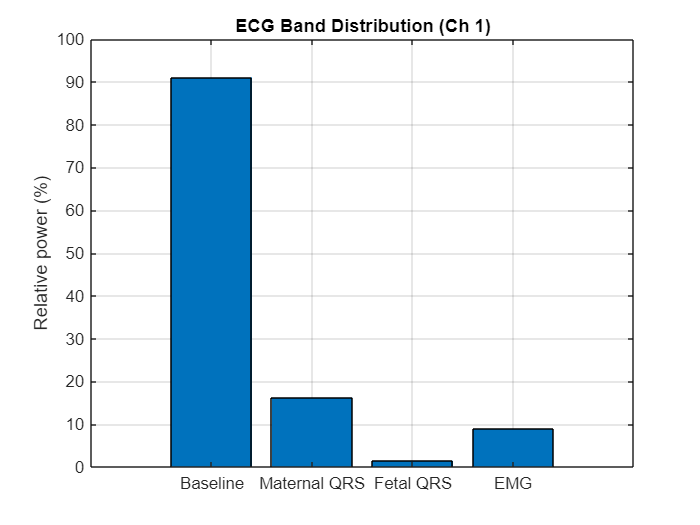


relP = zeros(size(bands,1),1);
for b = 1:size(bands,1)
    relP(b) = 100*bandpower(Pxx, fw, bands{b,2}, 'psd')/totalPower;
end
figure('Name','Band Power','Color','w');
bar(relP); set(gca,'XTickLabel',bands(:,1));
ylabel('Relative power (%)'); title('ECG Band Distribution (Ch 1)');
grid on;

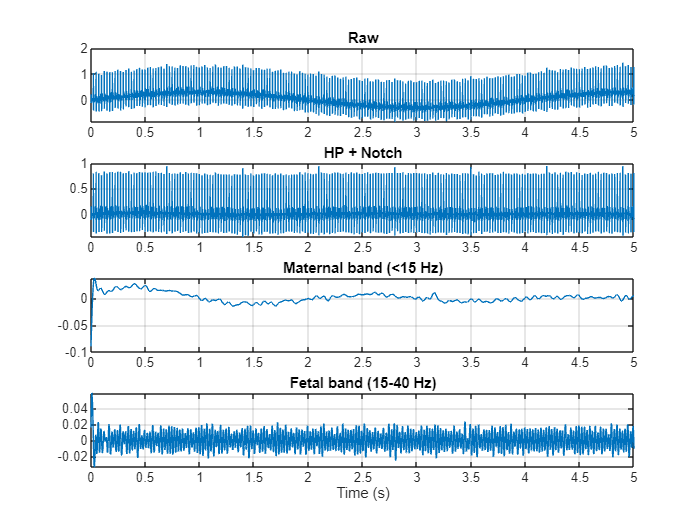

%% EXERCISE 5: Filtering
hp = designfilt('highpassiir','FilterOrder',4, ...
                'PassbandFrequency',0.5,'SampleRate',Fs);

wo = 50/(Fs/2); bw = wo/35;
[bN,aN] = iirnotch(wo, bw);

bp_f = designfilt('bandpassiir','FilterOrder',4, ...
                'HalfPowerFrequency1',15,'HalfPowerFrequency2',40, ...
                'SampleRate',Fs);

lp_m = designfilt('lowpassiir','FilterOrder',4, ...
                'PassbandFrequency',15,'SampleRate',Fs);

x_hp    = filtfilt(hp, x);
x_notch = filtfilt(bN, aN, x_hp);
x_fetal = filtfilt(bp_f, x_notch);
x_mat   = filtfilt(lp_m, x_notch);

figure('Name','Filtering','Color','w');
subplot(4,1,1); plot(t, x);       title('Raw');                 xlim([0 5]); grid on;
subplot(4,1,2); plot(t, x_notch); title('HP + Notch');          xlim([0 5]); grid on;
subplot(4,1,3); plot(t, x_mat);   title('Maternal band (<15 Hz)'); xlim([0 5]); grid on;
subplot(4,1,4); plot(t, x_fetal); title('Fetal band (15-40 Hz)');  xlim([0 5]); grid on;
xlabel('Time (s)');

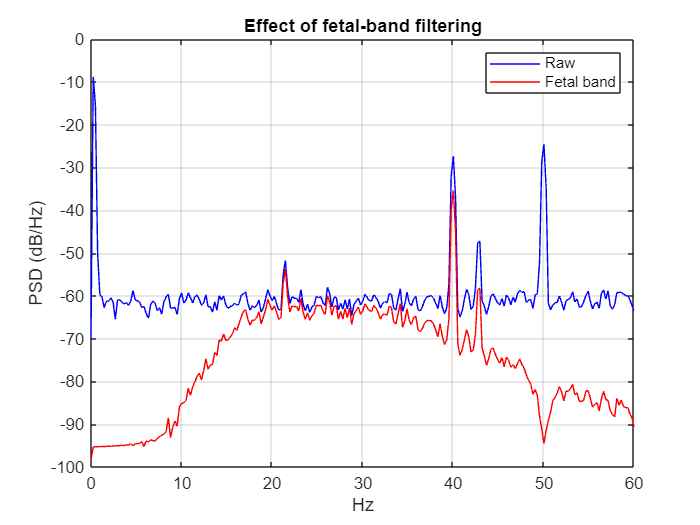


[Pxx_f, fw_f] = pwelch(x_fetal, window, noverlap, nfft, Fs);
figure('Name','PSD before/after','Color','w');
plot(fw,  10*log10(Pxx),   'b'); hold on;
plot(fw_f,10*log10(Pxx_f), 'r');
legend('Raw','Fetal band'); xlabel('Hz'); ylabel('PSD (dB/Hz)');
title('Effect of fetal-band filtering'); grid on; xlim([0 60]);

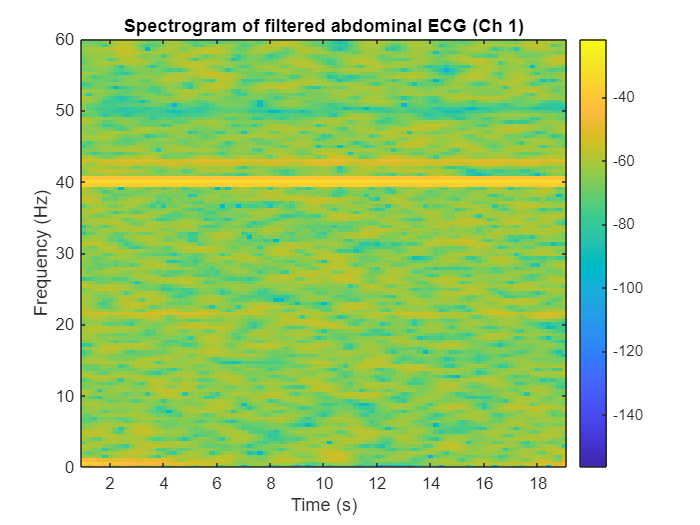

%% EXERCISE 6: STFT / Spectrogram
win_s  = 2;                        % 2 s window
nwin   = round(win_s*Fs);
nov    = round(0.9*nwin);
nfft2  = 2048;

figure('Name','Spectrogram','Color','w');
spectrogram(x_notch, hamming(nwin), nov, nfft2, Fs, 'yaxis');
title('Spectrogram of filtered abdominal ECG (Ch 1)');
ylim([0 60]); colorbar;

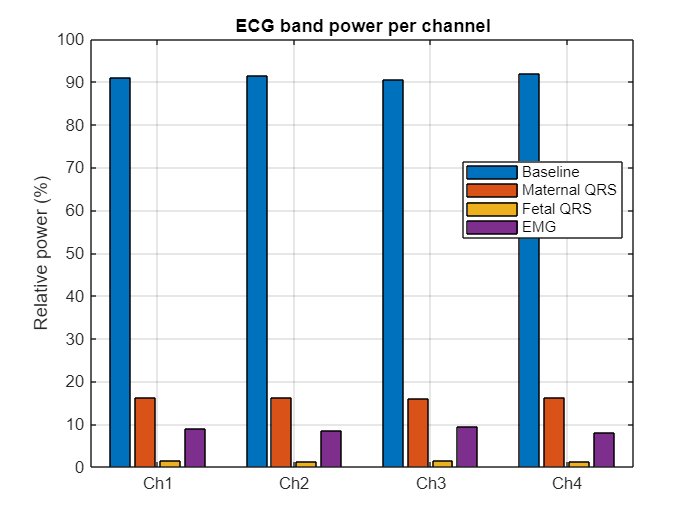

%% EXERCISE 7: Band power across channels
window   = hamming(4*Fs);
noverlap = round(0.5*length(window));
nfft     = 4096;

relP_ch = zeros(numCh, size(bands,1));
for ch = 1:numCh
    [Pxx_ch, fw_ch] = pwelch(ecg(ch,:), window, noverlap, nfft, Fs);
    tot = bandpower(Pxx_ch, fw_ch, [0.05 100], 'psd');
    for b = 1:size(bands,1)
        relP_ch(ch,b) = 100*bandpower(Pxx_ch, fw_ch, bands{b,2}, 'psd')/tot;
    end
end

figure('Name','Channel comparison','Color','w');
bar(relP_ch,'grouped');
set(gca,'XTickLabel', arrayfun(@(c) sprintf('Ch%d',c), 1:numCh, 'uni',0));
legend(bands(:,1),'Location','best');
ylabel('Relative power (%)'); title('ECG band power per channel');
grid on;